Fs = 1000;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = 1500;             % Length of signal
t = (0:L-1)*T;        % Time vector

%S = 0.7*sin(2*pi*50*t) + sin(2*pi*120*t);
S=6*sin(2*pi*49*t) + 8*sin(2*pi*129*t) +2*sin(2*pi*210*t);

X = S %+ 2*randn(size(t));

X =          0    9.5526   12.4188    8.5435    3.1664    0.2938   -0.1410    0.7998    3.5542    7.6802    9.3010    4.3020   -5.7780  -13.7075  -13.7675   -7.5325   -1.1916    1.4384    1.1787   -0.2218   -2.7039   -5.5771   -5.3528    0.8961   10.3986   15.8276   12.7812    4.4801   -2.2237   -4.0581   -2.8053   -0.8904    1.3116    3.1166    1.6102   -4.9903  -13.0034  -15.4369   -9.4459    0.2249    6.4381    6.8253    4.2706    1.7832   -0.1711   -1.1473    1.0862    7.2971   13.2475   12.6504


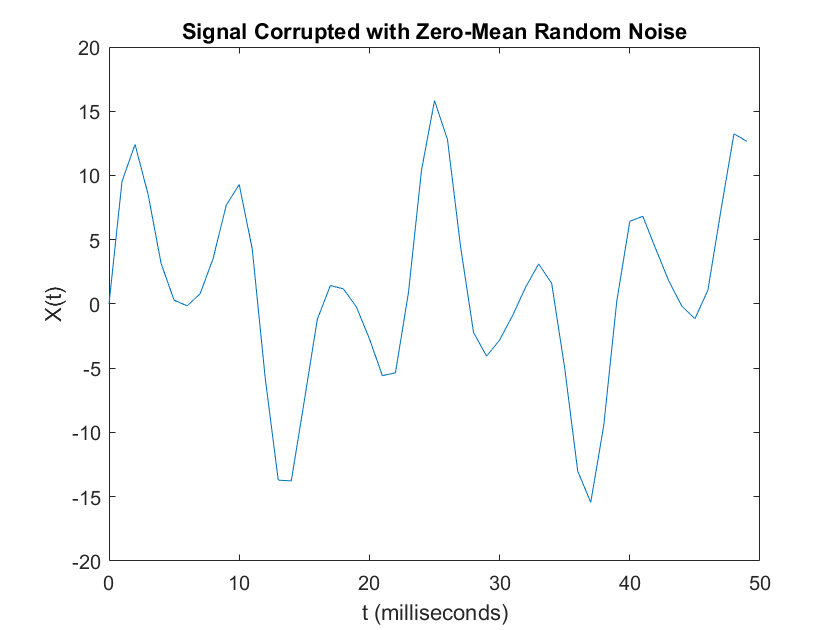


plot(1000*t(1:50),X(1:50))
title('Signal Corrupted with Zero-Mean Random Noise')
xlabel('t (milliseconds)')
ylabel('X(t)')

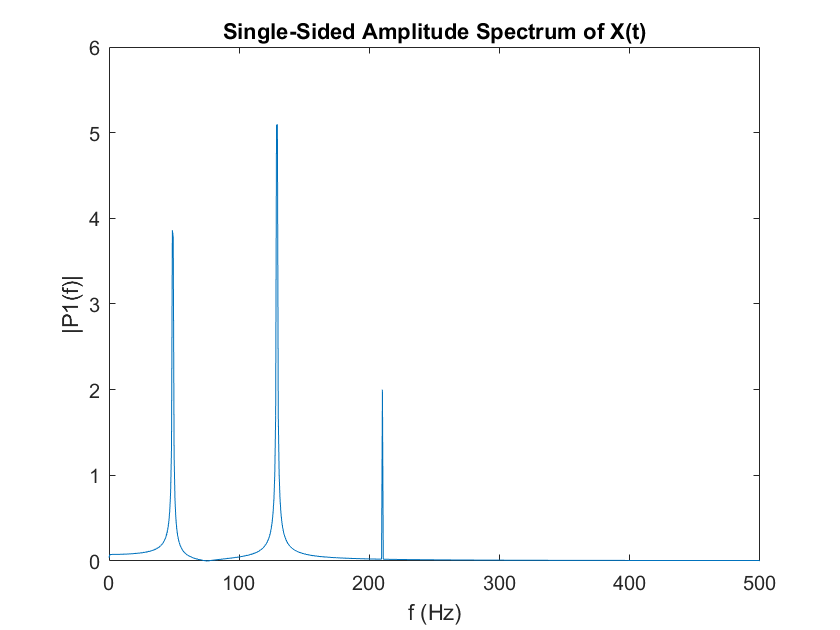


%%%%compute fourier transform
Y = fft(X);

P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')